## Power Flow

clc
clear all; close all;
cd("C:\Users\athul.p\Documents\GitHub\Power_System_Dynamics\HW6")
% cd("C:\Users\athul.p\Documents\GitHub\PowerSystemDynamic")
% Initializing Kundur 2 area system and importing data
n_bus = 11;
bus_data = importdata('ieee11bus.txt').data;
% bus_data = importdata('ieee11bus_allPV.txt').data;
branch_data = importdata('ieee11branch.txt').data;
   
% Ybus formation
t = 0; % 0 for without tap, 1 for with tap
Y = y_bus_calc(n_bus,bus_data,branch_data,t);

% Scheduled power calculation
base_MVA = 100;
P_inj = (bus_data(:,8) - bus_data(:,6)) / base_MVA;
Q_inj = (bus_data(:,9) - bus_data(:,7)) / base_MVA;

% Finding bus types
pv_i = find(bus_data(:,3) == 2);
pq_i = find(bus_data(:,3) == 0);
n_pv = length(pv_i);
n_pq = length(pq_i);

% Initializing Voltage magnitude and angles
V = bus_data(:,11);
V(V(:)==0) = 1;
T = zeros(n_bus,1);

% Newton Raphson Method
[V1_data,T1_data,T1] = NR(bus_data,V,T,P_inj,Q_inj,n_bus,Y,n_pq,pq_i);
% V = V1_data(:,end)
% T = T1_data(:,end)

% Fast Decoupled Mehod
%[V2_data,T2_data,T2] = FD(bus_data,V,T,P_inj,Q_inj,n_bus,Y,n_pq,pq_i);

% P,Q calculation after convergence
[P,Q] = PQ_calc(V1_data(:,size(V1_data,2)),T1_data(:,size(T1_data,2)),Y);
V = V1_data(:,size(V1_data,2));
T = T1_data(:,size(T1_data,2));
% [P,Q] = PQ_calc(V,T,Y)

% plotting convergence curves
% mplot([1:size(V1_data,2)],T1,[1:size(V1_data,2)],T1)

bus_data = importdata('ieee11bus_ynet.txt').data;
branch_data = importdata('ieee11branch_ynet.txt').data;
t = 0; % 0 for without tap, 1 for with tap
n_bus = 14;
Y = y_bus_calc(n_bus,bus_data,branch_data,t);

% calculating Ygen matrix

Y_gen = Y_gen_calc(Y)

Y_gen =        3.1519 -     12.697i       1.5578 +     7.2405i       1.0648 +     1.5522i       1.5415 +     2.1172i
       1.5578 +     7.2405i        1.299 -     10.992i      0.75503 +    0.97052i        1.088 +     1.3202i
       1.0648 +     1.5522i      0.75503 +    0.97052i       1.5317 -     8.3645i       1.8025 +     3.9505i
       1.5415 +     2.1172i        1.088 +     1.3202i       1.8025 +     3.9505i       2.6612 -     10.228i



P_gen = P(2:4);
Q_gen = Q(2:4);
V(12:14) = V(2:4);
T(12:14) = T(2:4);

% calculating Igen
I_gen = (P_gen - i*Q_gen)./(V(12:14).*exp(-i*T(12:14)));

X_gen = (((0.3+0.55)/2)*base_MVA/900);

% calculating Egen
E = (V(12:14).*exp(i*T(12:14))) + (i*X_gen.*I_gen);
[Theta, E_g] = cart2pol(real(E),imag(E))

Theta =       0.15413
      0.11778
    -0.044049


E_g =        1.0844
        1.127
       1.0748


E_g = [V(1); E_g]

E_g =          1.03
       1.0844
        1.127
       1.0748


Theta = [T(1); Theta]

Theta =             0
      0.15413
      0.11778
    -0.044049


## Dynamic Initialization (Type 3)

t = sym('t', [1 3]);
w = sym('w', [1 3]);

F = type3(t, w, P_gen, Y_gen, E_g);
solVal0 = [0, 0, 0, 1, 1, 1]

solVal0 =      0     0     0     1     1     1


vars = [t, w];

sol = vpasolve(F == 0, vars, solVal0)

## Small Signal Stability (Type 3)

trans_init = [];
% making Jacobian
for i = 1:length(vars)
    sol_val{i} = sol.(char(vars(i)));
    trans_init = [trans_init double(sol.(char(vars(i))))];
end
J = jacobian(F, vars);

% substituting solution
J_val = subs(J, vars, sol_val);
J_val = double(J_val);

% eigen value and vectors
[r_ev, eig_val] = eig(J_val);
l_ev = inv(r_ev);

% participation factor
norm_p = []; 
for i = 1: length(vars)
    p_mat = r_ev(:,i)*l_ev(i,:);
    diag_vec = abs(diag(p_mat));
    norm_p = [norm_p diag_vec./max(diag_vec)];
end

% calculating mode frequency
eigen_frequency_mode= abs(imag(diag(eig_val)))/2/pi;

## Transient Stability (Type 3)

% Ybus
Y_pre = Y;
Y_fault = y_fault_update();
Y_post = y_post_update();

% generating fault on system equations
Y_gen_fault = Y_gen_calc(Y_fault);
F_fault = type3(t, w, P_gen, Y_gen_fault, E_g);

% generating post fault system equations
Y_gen_post = Y_gen_calc(Y_post);
F_post = type3(t, w, P_gen, Y_gen_post, E_g);

% simulation parameters
h = 1e-3; Tf = 0; Tc = 6/60; Ts = 5;

% prefault scenario
x_init = trans_init;
[x_step, time_step] = Euler_step(h,x_init,F,vars,0,Tf-h);
x_data = [x_init' x_step];
time_data = [0 time_step];

% fault on scenario
x_init = x_data(:,end)';
[x_step, time_step] = Euler_step(h,x_init,F_fault,vars,Tf,Tf+Tc);
x_data = [x_data x_step];
time_data = [time_data time_step];

% post fault scenario
x_init = x_data(:,end)';
[x_step, time_step] = Euler_step(h,x_init,F_post,vars,Tf+Tc+h,Ts);
x_data = [x_data x_step];
time_data = [time_data time_step];

% seperating theta and omega variables
t_data = x_data(1:3,:);
w_data = x_data(4:6,:);

% plotting the graph
mplot(time_data, t_data, 'Theta')
mplot(time_data, w_data, 'Omega')


## Dynamic Initialization (Type 2)

t = sym('t', [1 3]);
w = sym('w', [1 3]);
Eq = sym('Eq', [1 3]);
Ed = sym('Ed', [1 3]);
Efd = sym('Efd', [1 3]);
Pm = sym('Pm', [1 3]);
Vref = sym('Vref', [1 3]);
Pc = sym('Pc', [1 3]);
Vw = sym('Vw', [1 2]);
Vc = sym('Vc', [1 2]);



vars = [t, w, Eq, Ed, Efd, Pm, Vref, Pc, Vw, Vc];
F = type2(t, w, Eq, Ed, Efd, Pm, Vref, Pc, Vw, Vc, P_gen, Y_gen, E_g, V, T);

x0 = [0.685 0.614 0.504  1 1 1  0.935 0.991 0.916  0.549 0.537 0.559  1.845 1.935 1.813  7.013 7.204 7.013 1.019 1.040 1.019 7.013 7.204 7.013 1 1 1 1];
sol = vpasolve(F,vars,x0)

sol = struct with fields:
       t1: 0.73012362529581486256165616895831
       t2: 0.65687498444885528450083883200644
       t3: 0.54783652526147714040723013222078
       w1: 1.0
       w2: 1.0
       w3: 1.0
      Eq1: 0.90946682821947830178734386990396
      Eq2: 0.96718862358221783399424028803851
      Eq3: 0.8918971361929880372965194348014
      Ed1: 0.59064544965806176089004041491732
      Ed2: 0.57858391571923695576703439000213
      Ed3: 0.59964666892862622808488483236939
     Efd1: 1.7448315172209092988170499089702
     Efd2: 1.8294497080311120987883089458004
     Efd3: 1.7184269984839945372313141225833
      Pm1: 7.0001442751686934996605646472464
      Pm2: 7.1897445895520757915049018062202
      Pm3: 6.9992763992011340352558251273426
    Vref1: 1.0012758424138954535059147504551
    Vref2: 1.020852751459844439506058455271
    Vref3: 1.0014078650075800273138434293871
      Pc1: 7.0001442751686934996605646472464
      Pc2: 7.1897445895520757915049018062202
      Pc3: 6.999276399

## Small Signal Stability (Type 2)

state_vars = [t, w, Eq, Ed, Efd, Pm];

% making Jacobian
J = jacobian(F(1:18), state_vars);
sol_val = {};
for i = 1:length(state_vars)
    sol_val{i} = sol.(char(state_vars(i)));
end

% substituting solution
J_val = subs(J, state_vars, sol_val);
J_val = double(J_val);

% eigen value and vectors
[r_ev, eig_val] = eig(J_val);
l_ev = inv(r_ev);

% participation factor
norm_p = []; 
for i = 1: length(state_vars)
    p_mat = r_ev(:,i)*l_ev(i,:);
    diag_vec = abs(diag(p_mat));
    norm_p = [norm_p diag_vec./max(diag_vec)];
end

% calculating mode frequency
eigen = diag(eig_val)

eigen =      -0.42089 +     6.3554i
     -0.42089 -     6.3554i
     -0.28902 +      5.657i
     -0.28902 -      5.657i
      -6.8438 +          0i
      -6.3271 +          0i
      -4.4875 +          0i
    -0.011982 +     3.3021i
    -0.011982 -     3.3021i
     -0.13194 +          0i


eigen_frequency_mode= abs(imag(eigen))/2/pi

eigen_frequency_mode =        1.0115
       1.0115
      0.90034
      0.90034
            0
            0
            0
      0.52555
      0.52555
            0


damping = -real(eigen)./abs(eigen)

damping =      0.066081
     0.066081
     0.051024
     0.051024
            1
            1
            1
    0.0036287
    0.0036287
            1


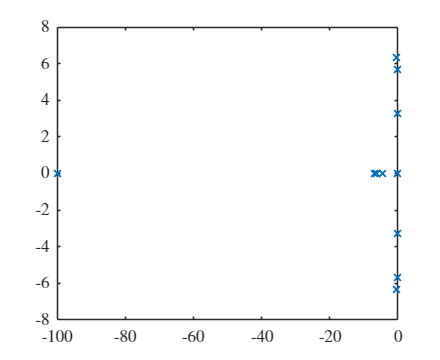



figure()
plot(real(eigen),imag(eigen),"x")

## PSS Analysis


pss_vars = [t, w, Eq, Ed, Efd, Pm, Vw, Vc];
F = type2_pss(t, w, Eq, Ed, Efd, Pm, Vref, Pc, Vw, Vc, P_gen, Y_gen, E_g, V, T);

sol = vpasolve(F,vars,x0)

sol = struct with fields:
       t1: 0.73012362529581486256165616895831
       t2: 0.65687498444885528450083883200644
       t3: 0.54783652526147714040723013222078
       w1: 1.0
       w2: 1.0
       w3: 1.0
      Eq1: 0.90946682821947830178734386990396
      Eq2: 0.96718862358221783399424028803851
      Eq3: 0.8918971361929880372965194348014
      Ed1: 0.59064544965806176089004041491732
      Ed2: 0.57858391571923695576703439000213
      Ed3: 0.59964666892862622808488483236939
     Efd1: 1.7448315172209092988170499089702
     Efd2: 1.8294497080311120987883089458004
     Efd3: 1.7184269984839945372313141225833
      Pm1: 7.0001442751686934996605646472464
      Pm2: 7.1897445895520757915049018062202
      Pm3: 6.9992763992011340352558251273426
    Vref1: 1.0012758424138954535059147504551
    Vref2: 1.020852751459844439506058455271
    Vref3: 1.0014078650075800273138434293871
      Pc1: 7.0001442751686934996605646472464
      Pc2: 7.1897445895520757915049018062202
      Pc3: 6.999276399

F_pss = [F(1:18);F(25:28)];

% making Jacobian
J = jacobian(F_pss, pss_vars);
sol_val = {};
for i = 1:length(pss_vars)
    sol_val{i} = sol.(char(pss_vars(i)));
end

% substituting solution
J_val = subs(J, pss_vars, sol_val);
J_val = double(J_val);

[r_ev, eig_val] = eig(J_val);
eigen_pss = diag(eig_val)

eigen_pss =          -100 +          0i
         -100 +          0i
     -0.60018 +     6.3558i
     -0.60018 -     6.3558i
     -0.45734 +     5.6573i
     -0.45734 -     5.6573i
      -6.3172 +          0i
       -6.827 +          0i
      -4.4984 +          0i
     -0.17707 +     3.3047i


eigen_frequency_mode_pss= abs(imag(eigen_pss))/2/pi

eigen_frequency_mode_pss =             0
            0
       1.0116
       1.0116
      0.90038
      0.90038
            0
            0
            0
      0.52596


damping_pss = -real(eigen_pss)./abs(eigen_pss)

damping_pss =             1
            1
     0.094013
     0.094013
     0.080579
     0.080579
            1
            1
            1
     0.053504


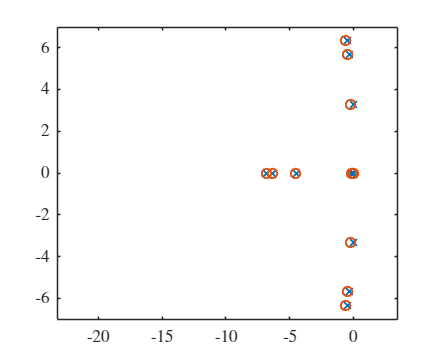


figure()

plot(real(eigen),imag(eigen),"x")
hold on
plot(real(eigen_pss),imag(eigen_pss),"o")

xlim([-120.0 20.0])
ylim([-20.0 20.0])

## Transient Stability (Type 2)

trans_init = [];
for i = 1:length(vars)
    trans_init = [trans_init double(sol.(char(vars(i))))];
end


% generating fault on system equations
Y_gen_fault = Y_gen_calc(Y_fault);
F_fault = type2(t, w, Eq, Ed, Efd, Pm, Vref, Pc, Vw, Vc, P_gen, Y_gen_fault, E_g, V, T);

% generating post fault system equations
Y_gen_post = Y_gen_calc(Y_post);
F_post = type2(t, w, Eq, Ed, Efd, Pm, Vref, Pc, Vw, Vc, P_gen, Y_gen_post, E_g, V, T);

% simulation parameters
h = 1e-3; Tf = 0; Tc = 6/60; Ts = 3;

% prefault scenario
x_init = trans_init;
[x_step, time_step] = Euler_step(h,x_init,F,vars,0,Tf-h);
x_data = [x_init' x_step];
time_data = [0 time_step];

% fault on scenario
x_init = x_data(:,end)';
[x_step, time_step] = Euler_step(h,x_init,F_fault,vars,Tf,Tf+Tc);
x_data = [x_data x_step];
time_data = [time_data time_step];

% post fault scenario
x_init = x_data(:,end)';
[x_step, time_step] = Euler_step(h,x_init,F_post,vars,Tf+Tc+h,Ts);
x_data = [x_data x_step];
time_data = [time_data time_step];

% seperating theta and omega variables
t_data = x_data(1:3,:);
w_data = x_data(4:6,:);


% plotting the graph
mplot(time_data, t_data, 'Theta')
mplot(time_data, w_data, 'Omega')